# B. System response and stability

Objective: 

- System response performance

- Analyze stability - poles and zeros

- Damping criteria 

Most of the system that in practical are second order and above. The problem of instability would not occur to forst order system. Therefore, form now, we will be studying systems of second order and above. As example, we will continue on the **case of mass spring system**.

M = 5;         % mass in kg
b = 0.5;        % viscuous friction in N/m/s^2
k = 1;         % spring elasticy in N/m
s = tf('s');
G_MassSpring = 1/(M*s^2 + b*s + k)    

G_MassSpring =
 
          1
  -----------------
  5 s^2 + 0.5 s + 1
 
Continuous-time transfer function.



### 1 - Closed-loop response

To control a system, a feedback loop is needed. The feedback loop is defined by the figure below.

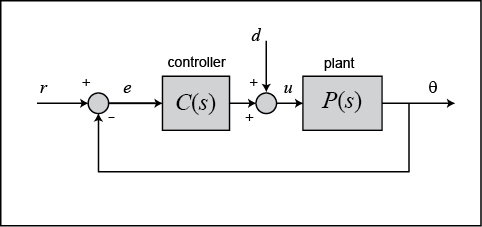

P(s) : The plant (the open loop system)

C(s) : The controller

d : disturbance from outside the system

r : input

theta : output

In this case, a sensor is needed to capture the actual response theta and be compared with the input r. The input and output are of the same physics (the former being the desired value, and the later the actual value) 

The closed-loop transfer function for the above with the controller *C*(*s*) simply set equal to 1 can be generated using the MATLAB command `feedback` as shown below.

G_MassSpring                        % open loop TF

G_MassSpring =
 
          1
  -----------------
  5 s^2 + 0.5 s + 1
 
Continuous-time transfer function.



sys_cl = feedback(G_MassSpring,1)   % closed loop TF

sys_cl =
 
          1
  -----------------
  5 s^2 + 0.5 s + 2
 
Continuous-time transfer function.



Remark that the equation is now different form the open loop transfer function developed in the previous chapter. The closed loop transfer function could be manually calculated using transfer function simplification/reduction method (Appendix 1 - Reduction transfer function)

Now, we can evaluate the response of the closed loop system by the following command:

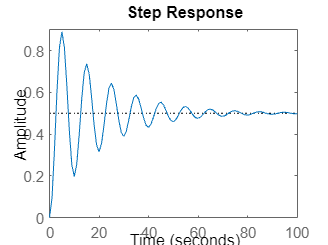

step(sys_cl,t)

Observation of the closed loop step response:

- Oscillations

- Settle at steady state after 100 seconds

There are several standard characteristic performance of a system. It can be found by Matlab by right clicking the figure and selecting characteristics. The data tips will show as follow. They are:

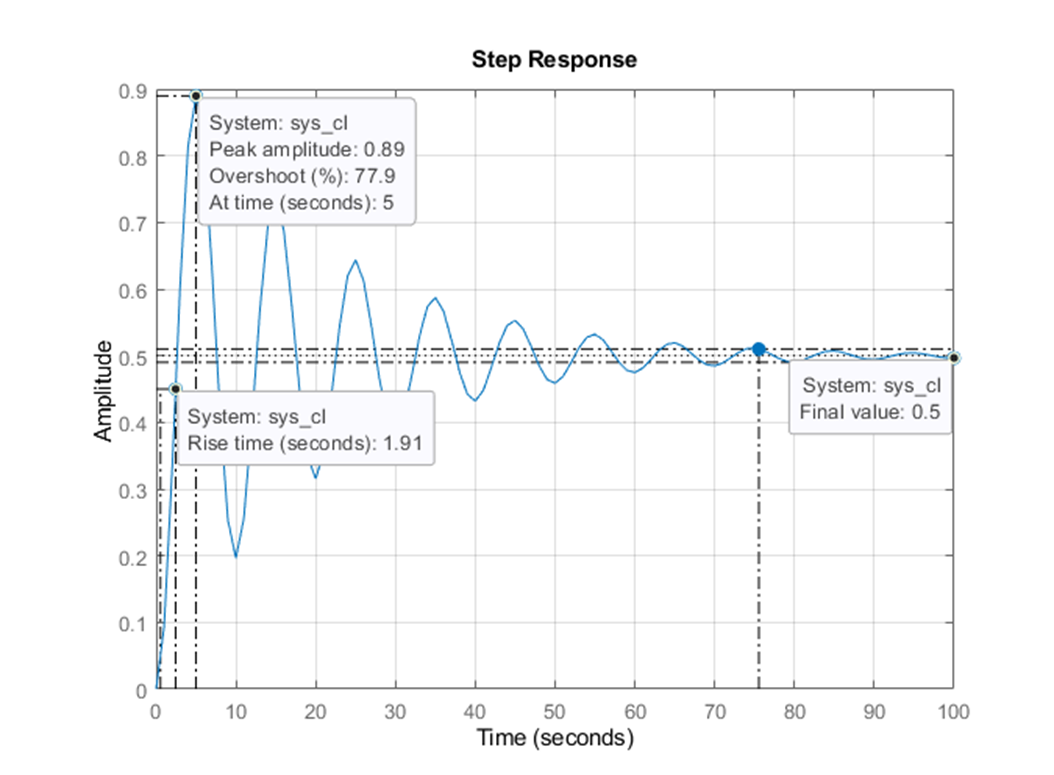

- Steady state: 0.5 m - final value

- Rise time: 1.91 seconds - times taken to reach 63% of the final value

- Overshoot: 77.9% at 0.89m - the maximum value surpassing the steady state value.

In a control system, these criteria will be defined by the system designer. A usually agreed good performance is a system with fast response (very small rise time) with very low overshoot. The steady state value should be as close as possible to the input value. In this case it should be very close to 1 (step input).

The difference between the input value (1m) and the actual response at steady state (0.5m) is called the **steady state error**. It should be reduced, tend towards zero (a precise system).

### 2 - Stability - Poles and zeros

Stability is defined by the ability of the system to have a steady state response value instead of non-convergent value. Our previous mass spring system is qualified as stable (regardless of the low performance).

For example, we can modify our mass spring system to turn it unstable. By reducing the damper b to a very small value, the mass could not settle to a steady state value. We change the parameter to as below and observe the step response:

M = 5;         % mass in kg
b = 0.001;     % viscuous friction in N/m/s^2 --> very low
k = 1;         % spring elasticy in N/m
s = tf('s');
G_MassSpring = 1/(M*s^2 + b*s + k)

G_MassSpring =
 
           1
  -------------------
  5 s^2 + 0.001 s + 1
 
Continuous-time transfer function.



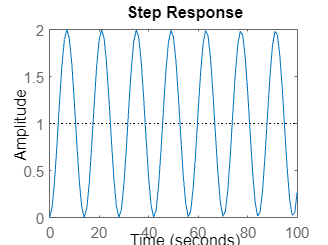

step(G_MassSpring, t)

Observation:

We can see that the position of the mass oscillate continuously between 0m and 2m without settlling to a steady state value. The system is now not stable because it does not converge. In fact this response is what we call a marginally stable system.

A system can be classified into **3 categories**:

- **Stable** system : Converge to a finite steady state value

- **Marginally stable** system: Does not converge, but oscillate around a certain average value

- **Unstable system**: Does not converge. Tends towards infinity (positive or negative)

By observing the transfer function, the stability of the system can be predicted through its **poles** values and position.

**Poles**

Definition: 

- Points in the complex plane (s-plane)

- Found by the values that turn the denominator zero (solution to the denominator) of the transfer function

Example:

We recall the transfer function of the open loop mass spring system:

G_MassSpring

G_MassSpring =
 
           1
  -------------------
  5 s^2 + 0.001 s + 1
 
Continuous-time transfer function.



The denominator is a polynomial of quadratic equation. We know that the solution that will make the denominator zero is:

So, we can find the poles, which is the roots of the polynomials using the above equations:

% Define the coefficients of the quadratic equation
a = 5;
b = 0.001;
c = 1;

% Find the roots
roots_of_quadratic = roots([a, b, c])

roots_of_quadratic =   -0.0001 + 0.4472i
  -0.0001 - 0.4472i


We found that there are 2 poles in the form of complex numbers. This number can be plotted in the complex s-plane. It can be done in Matlab directly by:

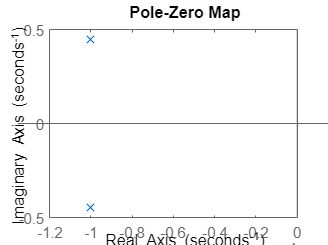

pzmap(G_MassSpring)

 As we have mentioned previously, this system is marginally stable. So, the stability criteria can be divided as follows:

- Stable system: All the poles are Real numbers and located on the left of the plane (negative values)

- Marginally stable system: All the poles are purely imaginary numbers. The real components of the poles is zero

- Unstable system: At least one of the poles has is located on the right of the s-plane (has positive real number component)

The following are examples of the 3 category of stability:

#### Stable system

% Define the stable transfer function
G_stable = tf(1, [1, 4, 4])

G_stable =
 
        1
  -------------
  s^2 + 4 s + 4
 
Continuous-time transfer function.



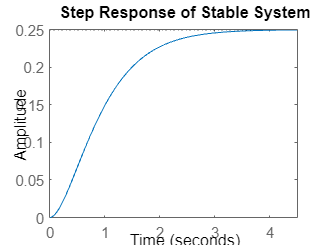


% Plot the step response
figure;
step(G_stable);
title('Step Response of Stable System');

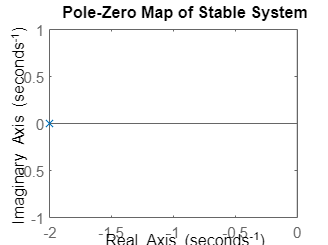


% Plot the pole-zero map
figure;
pzmap(G_stable);
title('Pole-Zero Map of Stable System');

#### Marginally stable system

% Define the marginally stable transfer function
G_marginally_stable = tf(1, [1, 0, 0])

G_marginally_stable =
 
   1
  ---
  s^2
 
Continuous-time transfer function.



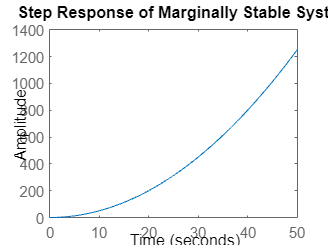


% Plot the step response
figure;
step(G_marginally_stable);
title('Step Response of Marginally Stable System');

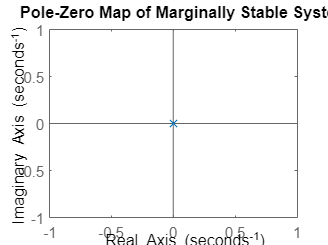


% Plot the pole-zero map
figure;
pzmap(G_marginally_stable);
title('Pole-Zero Map of Marginally Stable System');

#### Unstable system

% Define the unstable transfer function
G_unstable = tf(1, [1, -4, 4])

G_unstable =
 
        1
  -------------
  s^2 - 4 s + 4
 
Continuous-time transfer function.



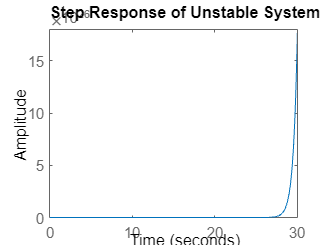


% Plot the step response
figure;
step(G_unstable);
title('Step Response of Unstable System');

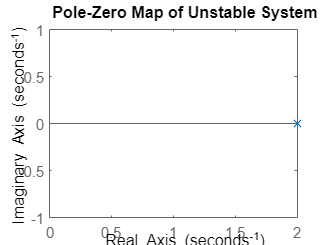


% Plot the pole-zero map
figure;
pzmap(G_unstable);
title('Pole-Zero Map of Unstable System');

The stability of a system can be simply checked in Matlab by asking the stability:

isstable(G_MassSpring)

ans = logical
   1


Answer 1 indicate stability.

### 3 - Damping criteria

Particularly for a stable second order system, the transfer function can also be defined by its damping criteria. It is classified by how much overshoot and ripple the response generates.

The damping criterias are:

- Overdamped system

- Critically-damped system 

- Under-damped system

- Undamped system

For an oscillating system, we can always identify its damping coefficient and natural frequency.

Examples:

1.Overdamped

% Define the overdamped system
G_overdamped = tf(9, [1, 9, 9])

G_overdamped =
 
        9
  -------------
  s^2 + 9 s + 9
 
Continuous-time transfer function.



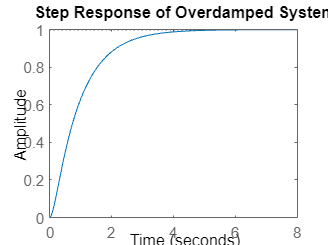


% Plot the step response
figure;
step(G_overdamped);
title('Step Response of Overdamped System');

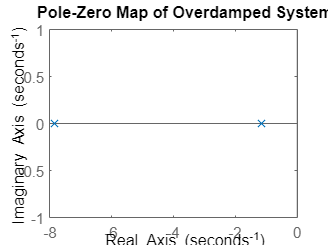


% Plot the pole-zero map
figure;
pzmap(G_overdamped);
title('Pole-Zero Map of Overdamped System');


% Identify the damping coefficient and natural frequency
damp(G_overdamped)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.15e+00     1.00e+00       1.15e+00         8.73e-01    
 -7.85e+00     1.00e+00       7.85e+00         1.27e-01    


2. Critically-damped 

% Define the critically-damped system
G_criticdamped = tf(9, [1, 6, 9])

G_criticdamped =
 
        9
  -------------
  s^2 + 6 s + 9
 
Continuous-time transfer function.



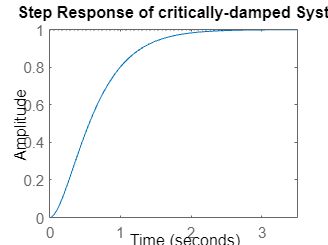


% Plot the step response
figure;
step(G_criticdamped);
title('Step Response of critically-damped System');

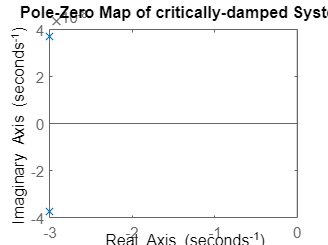


% Plot the pole-zero map
figure;
pzmap(G_criticdamped);
title('Pole-Zero Map of critically-damped System');


% Identify the damping coefficient and natural frequency
damp(G_criticdamped)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.00e+00 + 3.73e-08i     1.00e+00       3.00e+00         3.33e-01    
 -3.00e+00 - 3.73e-08i     1.00e+00       3.00e+00         3.33e-01    


3. Under-damped 

% Define the under-damped system
G_underdamped = tf(9, [1, 2, 9])

G_underdamped =
 
        9
  -------------
  s^2 + 2 s + 9
 
Continuous-time transfer function.



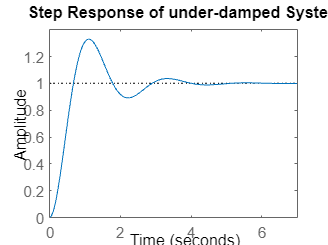


% Plot the step response
figure;
step(G_underdamped);
title('Step Response of under-damped System');

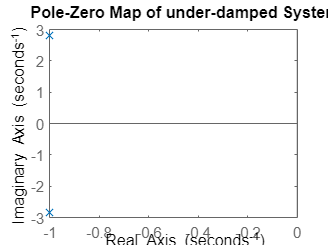


% Plot the pole-zero map
figure;
pzmap(G_underdamped);
title('Pole-Zero Map of under-damped System');


% Identify the damping coefficient and natural frequency
damp(G_underdamped)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 2.83e+00i     3.33e-01       3.00e+00         1.00e+00    
 -1.00e+00 - 2.83e+00i     3.33e-01       3.00e+00         1.00e+00    


4. Undamped

% Define the undamped system
G_undamped = tf(9, [1, 0, 9])

G_undamped =
 
     9
  -------
  s^2 + 9
 
Continuous-time transfer function.



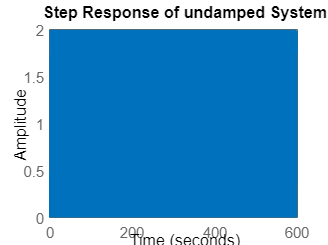


% Plot the step response
figure;
step(G_undamped);
title('Step Response of undamped System');

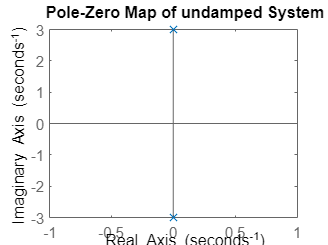


% Plot the pole-zero map
figure;
pzmap(G_undamped);
title('Pole-Zero Map of undamped System');


% Identify the damping coefficient and natural frequency
damp(G_undamped)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  0.00e+00 + 3.00e+00i     0.00e+00       3.00e+00           Inf       
  0.00e+00 - 3.00e+00i     0.00e+00       3.00e+00           Inf       


### **3 - Reflections**

- Identify the region of stability on an s-plane. Give an example of a system that falls under each stability criteria (complete with its transfer function).

- Identify the difference of the poles position in terms of its damping criteria? WHat are their corresponding damping value? (For all overdamped, critically damped, under-damped, and undamped)

- For each system in the example of damping criteria, find the performance criteria of rise time, overshoot, and steady state value

## Reference 

[1]    Norman S. Nise, “CONTROL SYSTEMS ENGINEERING Eighth Edition,” UMP** Repository**, accessed September 21, 2023, https://repository.gctu.edu.gh/items/show/477.

[2] *DC Motor Position: System Modeling*. Control Tutorials for MATLAB and Simulink - Motor Position: System Modeling. (n.d.). https://ctms.engin.umich.edu/CTMS/index.php?example=MotorPosition&section=SystemModeling 